# Convolucion y propiedades

## Operaciones de convolucion

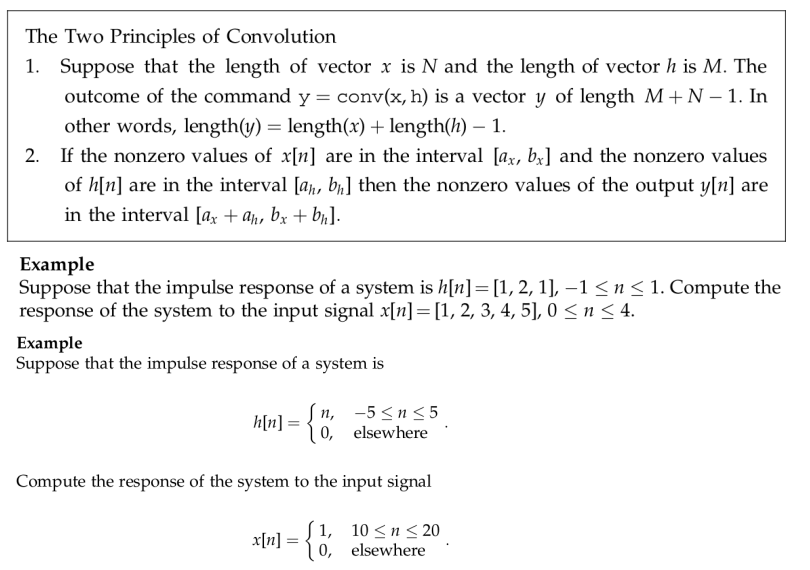

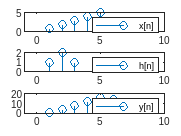

%1
h = [1,2,1];
x = [1,2,3,4,5];

y = conv(x,h);

x_lim = [-1 10];

figure
subplot(3,1,1)
stem(x)
xlim(x_lim)
legend("x[n]")
subplot(3,1,2)
stem(h)
xlim(x_lim)
legend("h[n]")
subplot(3,1,3)
stem(y)
xlim(x_lim)
legend("y[n]")

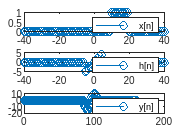



%2
clear
syms t

%x_lim = [-1 10];
n = -40:40;
x_lim = [min(n) max(n)];
h = t*(heaviside(t+5)-heaviside(t-5));
h = subs(h,t,n);
x = heaviside(t-10)- heaviside(t-20);
x = subs(x,t,n);

y = conv(double(x),double(h));

%Cuadrar bien el n_y
%n_y = [-5+10:5+20];

figure
subplot(3,1,1)
stem(n,x)
xlim(x_lim)
legend("x[n]")
subplot(3,1,2)
stem(n,h)
xlim(x_lim)
legend("h[n]")
subplot(3,1,3)
%Por terminar
stem(y)
%xlim(x_lim)
legend("y[n]")

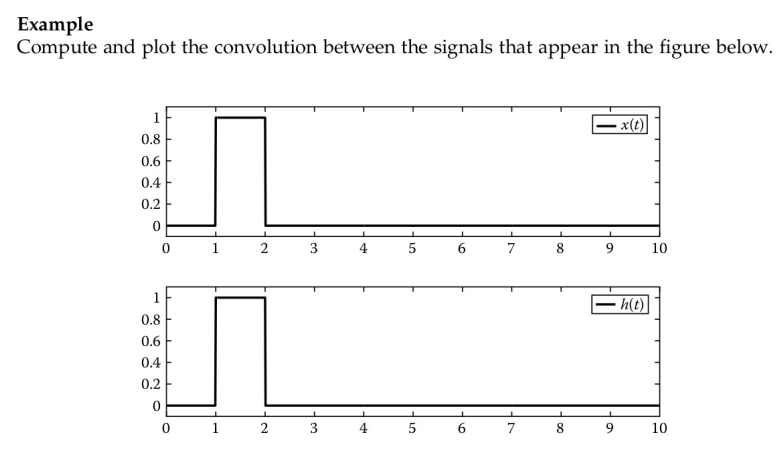

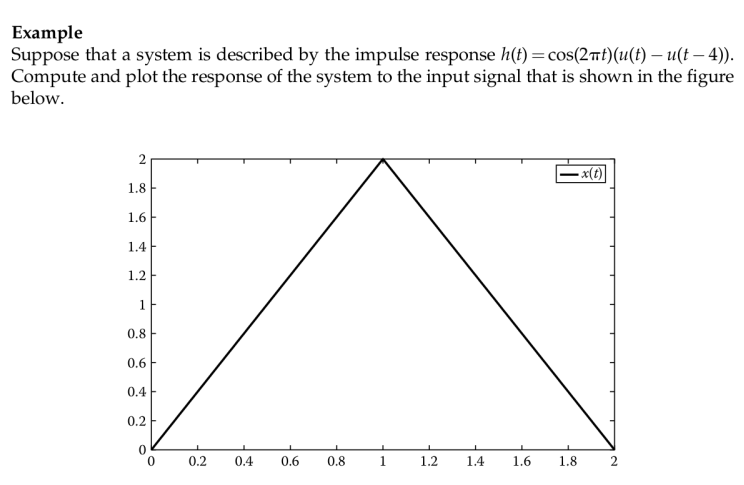

Usar definicion de la integral convolutiva y variables simbolicas

% 1
clear
syms t tau

x = heaviside(t-1)-heaviside(t-2);
h = x;

%Definición de convolucion

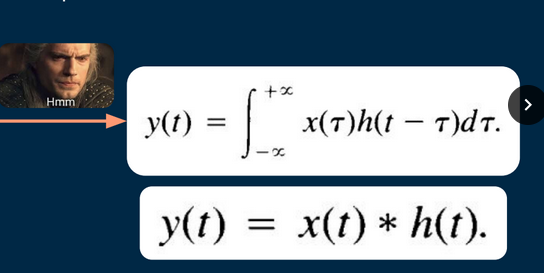

y = int(subs(x,t,tau)*subs(h,t,t-tau),tau,-inf,inf)

$$y = \mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-2\,\mathrm{heaviside}\left(t-3\right)\,\left(t-3\right)+\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)$$

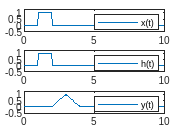


x_lim = [0 10];
y_lim = [-0.5 1.2];

figure
subplot(3,1,1)
fplot(x)
xlim(x_lim)
ylim(y_lim)
legend("x(t)")
subplot(3,1,2)
fplot(h)
xlim(x_lim)
ylim(y_lim)
legend("h(t)")
subplot(3,1,3)
fplot(y)
xlim(x_lim)
ylim(y_lim)
legend("y(t)")

## Propiedades

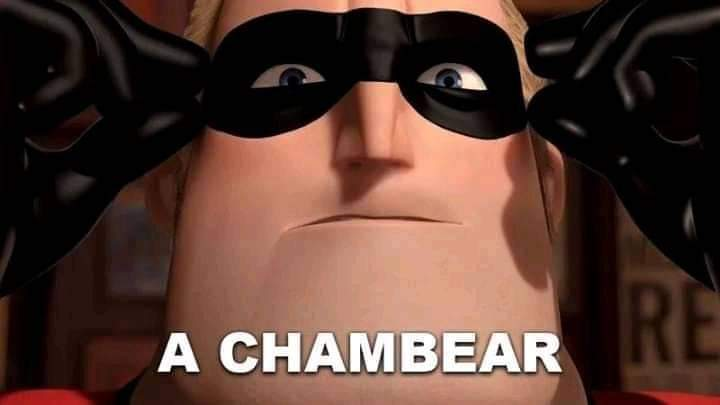

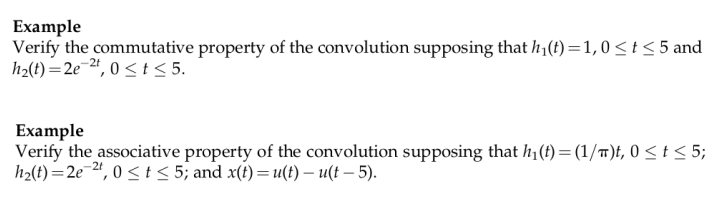

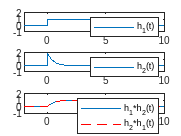

% En honor a Rodrigo, porque lo intentó
% 1
clear

syms t tau

h1 = heaviside(t)-heaviside(t-5);
h2 = 2*exp(-2*t)*(heaviside(t)-heaviside(t-5));

h1h2 = int(subs(h1,t,tau)*subs(h2,t,t-tau),tau,-inf,inf);
h2h1 = int(subs(h2,t,tau)*subs(h1,t,t-tau),tau,-inf,inf);


x_lim = [-2 10]; y_lim = [-1 2];

figure
subplot(3,1,1)
fplot(h1,x_lim)
ylim(y_lim)
legend("h_1(t)")
subplot(3,1,2)
fplot(h2,x_lim)
ylim(y_lim)
legend("h_2(t)")
subplot(3,1,3)
fplot(h1h2,x_lim)
hold on
fplot(h2h1,x_lim,'r--')
ylim(y_lim)
legend("h_1*h_2(t)","h_2*h_1(t)")

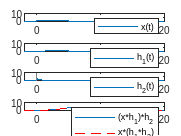


%2
clear

syms t tau

h1 = (1/pi)*t*(heaviside(t)-heaviside(t-5));
h2 = 2*exp(-2*t)*(heaviside(t)-heaviside(t-5));
x = heaviside(t)-heaviside(t-5);

% (x*h1)*h2
xh1 = int(subs(x,t,tau)*subs(h1,t,t-tau),tau,-inf,inf);
xh1h2 = int(subs(xh1,t,tau)*subs(h2,t,t-tau),tau,-inf,inf);

% x*(h1*h2)
h1h2 = int(subs(h1,t,tau)*subs(h2,t,t-tau),tau,-inf,inf);
h1h2x = int(subs(h1h2,t,tau)*subs(x,t,t-tau),tau,-inf,inf);

x_lim = [-2 20]; y_lim = [-1 10];
figure
subplot(4,1,1)
fplot(x,x_lim)
ylim(y_lim)
legend("x(t)")
subplot(4,1,2)
fplot(h1,x_lim)
ylim(y_lim)
legend("h_1(t)")
subplot(4,1,3)
fplot(h2,x_lim)
ylim(y_lim)
legend("h_2(t)")
subplot(4,1,4)
fplot(xh1h2,x_lim)
hold on
fplot(h1h2x,x_lim,'r--')
ylim(y_lim)
legend("(x*h_1)*h_2","x*(h_1*h_2)")

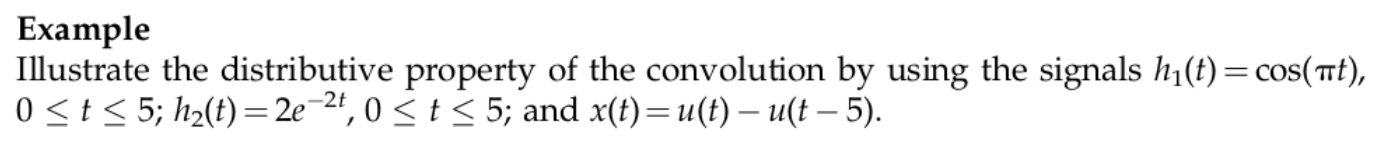

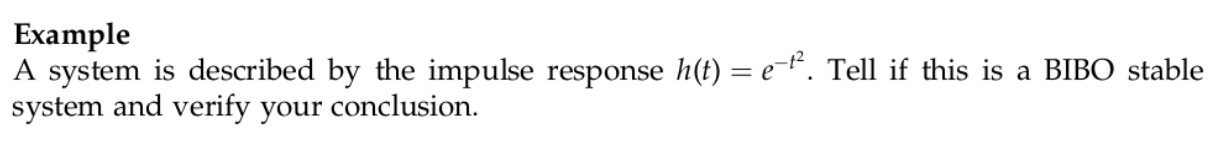

**A mano**

1.- Probar que un sistema con respuesta al impulso unitario $h\left(t\right)=\delta \left(t-t_0 \right)$ es estable

2.- Comprobar que el sistema con respuesta unitaria $h\left(t\right)=u\left(t\right)$ tiene como inversa $h\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -\delta \;\left\lbrack n-1\right\rbrack$